close all
clear
clc

定义系统

a = [1, -1, 0.24];
b = [1, -1];

定义仿真时刻和激励序列

n = [0:20]';
x = n.^2;

定义起始状态

wi = [-a(3)*(-2)-a(2)*(-1),-a(3)*(-1)];

滤波

[y, wf] = filter(b, a, x, wi);

绘图

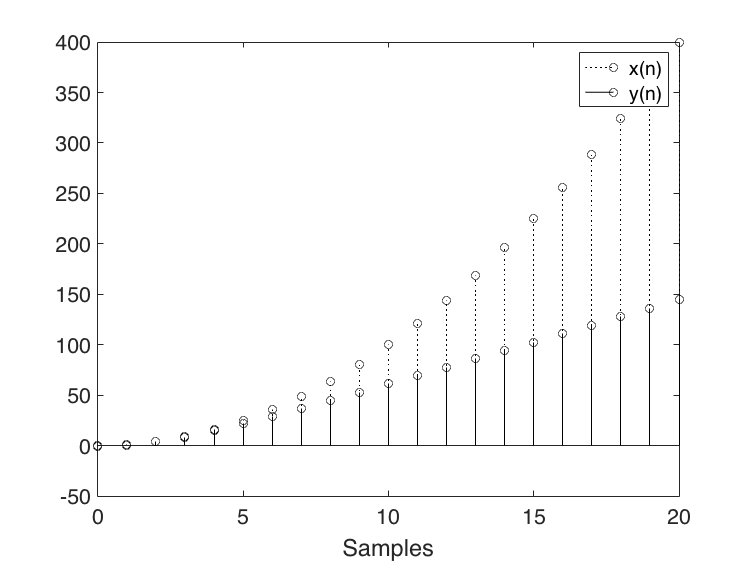

figure, box on, hold on;
stem(n,x,'k:');
stem(n,y,'k-');
set(gca,'FontSize',16);
xlabel('Samples');
legend('x(n)','y(n)');